# Inner Controller Identification

## Plant Model:

This model should be correct. The parameters are good, the output it produces lines up with what I found in the thesis.

Iyy  =  34.7e-3;  % kg m^2
dM_q = -46.3e-3;  % N m s
dM_u =  15e-3;    % Nms

A = [
    1 / Iyy * dM_q,  0;
    1                0;
];

B = [1 / Iyy * dM_u; 0];
C = [1 0];
D = 0;

PitchRateModel = ss(A, B, C, D, ...
    'InputName', 'Delta Omega', 'OutputName', 'Pitch Rate (q)');

Mixer = dM_u^-1;

PlantModel = PitchRateModel * Mixer;

## Controller (PID

There was some confusion over the parameters of the inner controller initially but these should be the correct values.

Controller = pid(.3, .3, .05, .01);

## Reference Model. 

In this bastardised version of VRFT we use the compl. sensitivity of the loop to build the reference model.

cloop = loopsens(PlantModel, Controller);
ReferenceModel = cloop.Ti;

We need to discretize these models to do anything.

Ts = .001;
    
PlantModel_dt     = c2d(tf(PlantModel), Ts);
ReferenceModel_dt = c2d(tf(ReferenceModel), Ts);

% bode(ReferenceModel_dt); grid on; title('Bode Diagram of The Reference Model');

## VRFT Time with PRBS

First we make the I/O data

% I/O Signals
N = 16 / Ts;
time = [0:(N-1)] * Ts;

% The parameters used here are the same used in the other scripts
u = idinput(N, 'prbs', [0 .015], [-1.5, 1.5]);

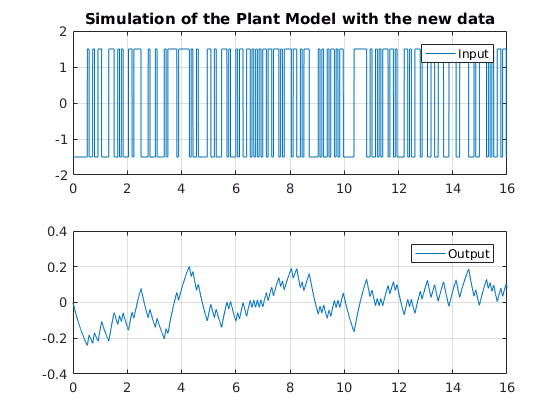

% y = lsim(PlantModel_dt, u, time);
y = lsim(PitchRateModel, u, time);

figure()
    subplot 211
        plot(time, u); legend('Input');
        title('Simulation of the Plant Model with the new data');
    subplot 212 
        plot(time, y), legend('Output');

The controller class:

% Use continuous PID, then discretize
Tf = .01;
ControllerClass = [ 1, tf(1, [1 0]), tf([1 0], [Tf 1]) ].';
ControllerClass_dt = c2d(ControllerClass, Ts);

% Use Discrete PID
% Ni = 1 / Tf;
% ControllerClass_dt = [ 1, Ts * tf([1 0], [1 -1], Ts), tf([Ni, -Ni], [1, -1+Ni*Ts], Ts)] .';

And run the VRFT engine.

Note: `VRFT1_ry_theta` is an extension of the `VRFT1_ry` method that also exposes the value of the parameter vector. The only changes from the original file are related to this. 

% ol_data = load('dati_id_ol.mat');
% dM = ol_data.u / Mixer;
% 
% mk_2nd_order = @(omega, zeta) tf(omega^2, [1, 2*omega*zeta, omega^2]);
% ReferenceModel = mk_2nd_order(10, .7);
% ReferenceModel_dt = c2d(ReferenceModel, Ts) * tf(1, [1 0 0 0 0], Ts);
% 
% [OptimalController, Theta] = ...
%     VRFT1_ry_theta(dM, ol_data.y, ReferenceModel_dt, ControllerClass_dt, [], 3, []);
 
[OptimalController, Theta] = ...
    VRFT1_ry_theta(u / Mixer, y, ReferenceModel_dt, ControllerClass_dt, [], [], []);

fprintf('The optimal PID parametters for the inner controller are: \n');

The optimal PID parametters for the inner controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', Theta(1), Controller.Kp);

Kp = +0.341159, Original: 0.3    


fprintf('Ki = %+7g, Original: %-7g\n', Theta(2), Controller.Ki);

Ki = +0.202311, Original: 0.3    


fprintf('Kd = %+7g, Original: %-7g\n', Theta(3), Controller.Kd);    

Kd = +0.0439105, Original: 0.05   



cloop = loopsens(PlantModel_dt, OptimalController); 

disp('#==============')

#==============


disp('Compl. Sensitivity with OptimalController:')

Compl. Sensitivity with OptimalController:


tf(cloop.Ti)


ans =
 
  From input "du" to output "uC":
   0.1334 z^2 - 0.2658 z + 0.1324
  ---------------------------------
  z^3 - 2.77 z^2 + 2.541 z - 0.7712
 
Sample time: 0.001 seconds
Discrete-time transfer function.



disp(' ')

disp('Reference Model:')

Reference Model:


ReferenceModel_dt


ReferenceModel_dt =
 
  From input "du" to output "uC":
    0.1326 z^2 - 0.2644 z + 0.1318
  ----------------------------------
  z^3 - 2.777 z^2 + 2.555 z - 0.7782
 
Sample time: 0.001 seconds
Discrete-time transfer function.



disp('#==============')

#==============


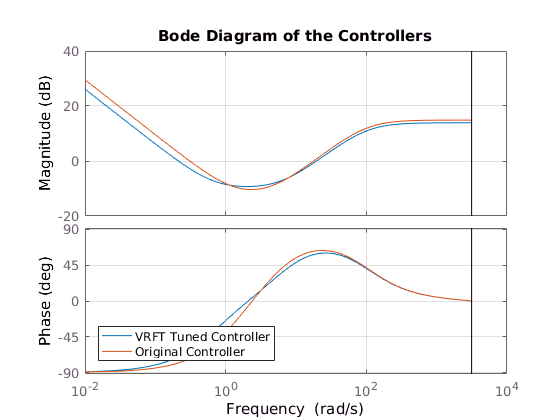


figure()
    bode(OptimalController, c2d(Controller, Ts));
    title('Bode Diagram of the Controllers'); 
    legend('VRFT Tuned Controller', 'Original Controller', 'location', 'SouthWest');
    grid on;

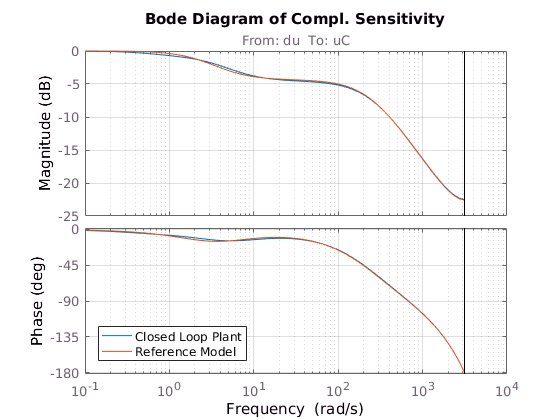


figure()
    bode(cloop.Ti, ReferenceModel_dt);
    title('Bode Diagram of Compl. Sensitivity');
    legend('Closed Loop Plant', 'Reference Model', 'location', 'SouthWest');
    grid on;

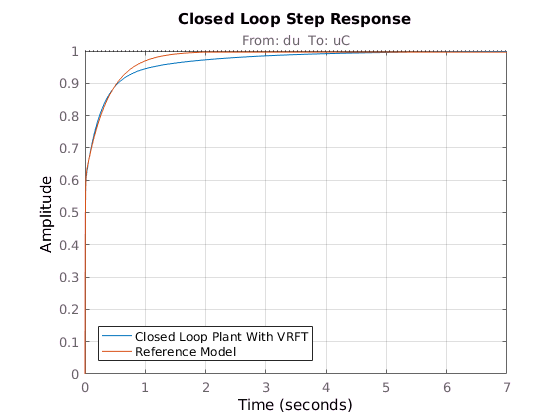

    
figure()
    step(cloop.Ti, ReferenceModel_dt);
    title('Closed Loop Step Response');
    legend('Closed Loop Plant With VRFT', 'Reference Model', 'location', 'SouthWest');
    grid on;    